clc
clear all
close all

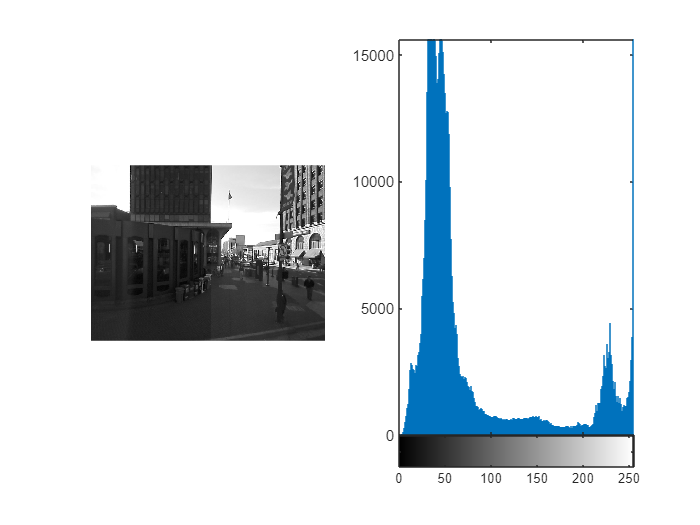

% Read in images
II = imread('pic.jpg');
I = II;
figure
subplot(1,2,1)
imshow(I)
subplot(1,2,2)
imhist(I,256)

% Convert image to double precision
IP = double(II);
D = linspace(0,26,27)*10;
for i=1:26
    % Create a binary mask for each range of pixel values
    H(:,:,i) = IP>D(i) & IP<D(i+1);
end

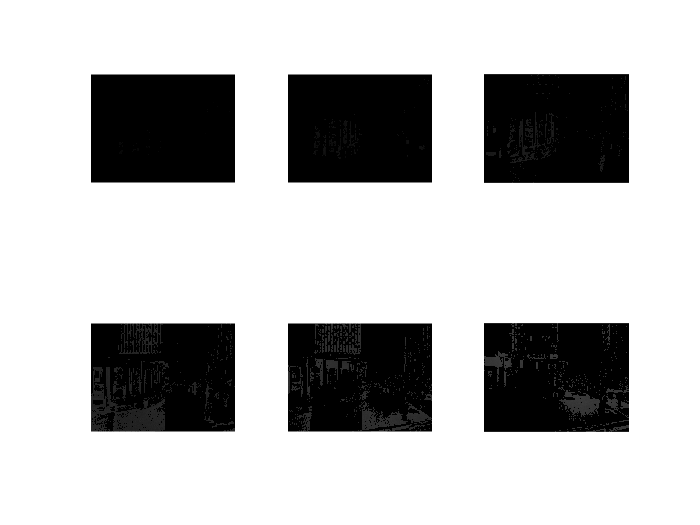

figure
% Display the binary masks for the first 26 ranges of pixel values
for i=1:6
    subplot(2,3,i)
    F(:,:,i) = H(:,:,i).*IP;
    imshow(uint8(F(:,:,i)))
end

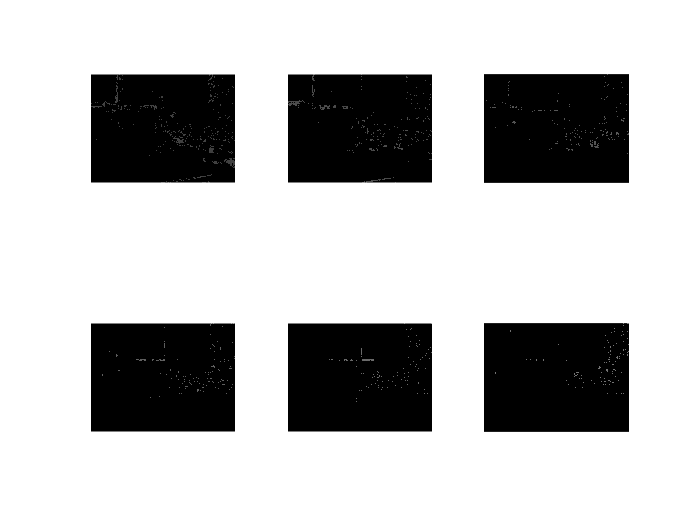

figure
for i=7:12
    subplot(2,3,i-6)
    F(:,:,i) = H(:,:,i).*IP;
    imshow(uint8(F(:,:,i)))
end

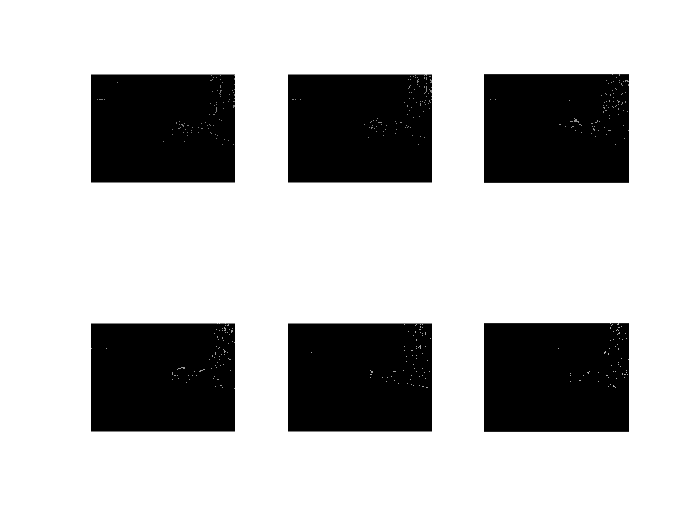

figure
for i=13:18
    subplot(2,3,i-12)
    F(:,:,i) = H(:,:,i).*IP;
    imshow(uint8(F(:,:,i)))
end

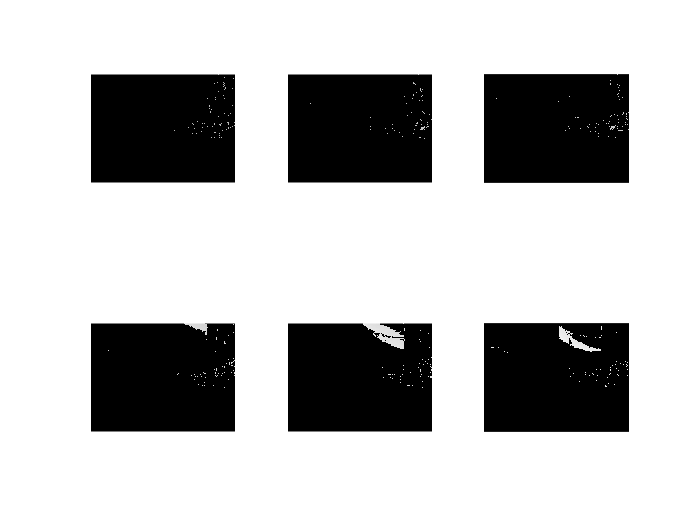

figure
for i=19:24
    subplot(2,3,i-18)
    F(:,:,i) = H(:,:,i).*IP;
    imshow(uint8(F(:,:,i)))
end

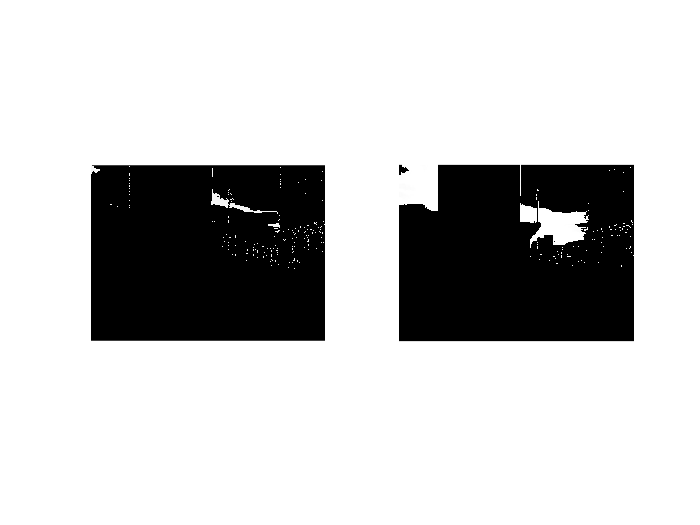

figure
for i=25:26
    subplot(1,2,i-24)
    F(:,:,i) = H(:,:,i).*IP;
    imshow(uint8(F(:,:,i)))
end

shifting cololr value

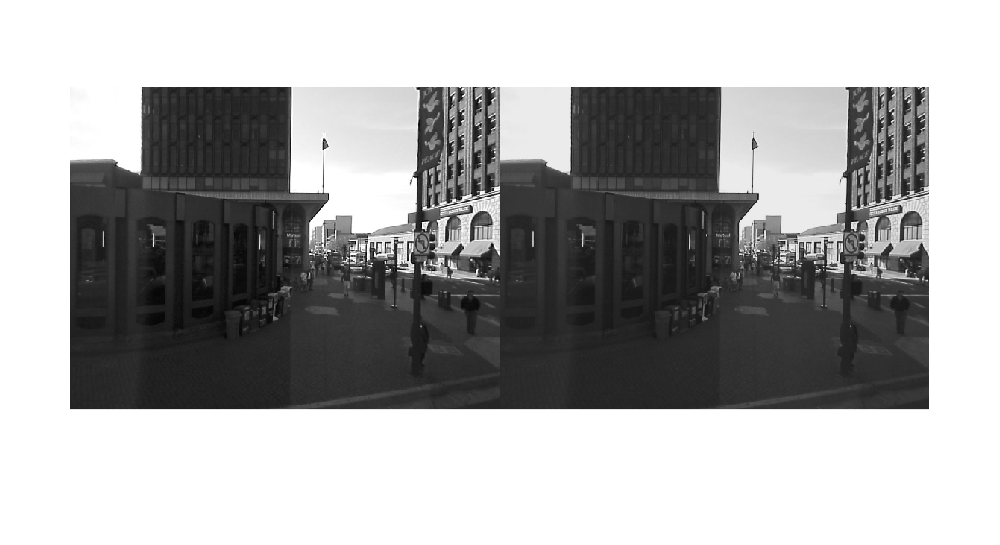

Ipp = double(II);
[n , m] =size(I);
% Shifting color value using a piecewise cubic function with two segments 
D = 55;
A = 10;
for i=1:n
    for j=1:m
        temp = Ipp(i,j);
        if temp < D
            Error = (A/(D))*(temp -D) + (A/(D)^3)*(temp -D)^3 ;
            Ipp(i,j) = floor(Ipp(i,j)-Error)+1;
        else 
            Error = (A/((255-D)^4))*(temp - D)^4 + (A/(255-D))*(temp - D); 
            Ipp(i,j) = floor(Ipp(i,j)-Error);
        end
    end
end
% Display a montage of the original image and the modified image,
% as well as their histograms.
figure
figure
montage({II,uint8(Ipp)})

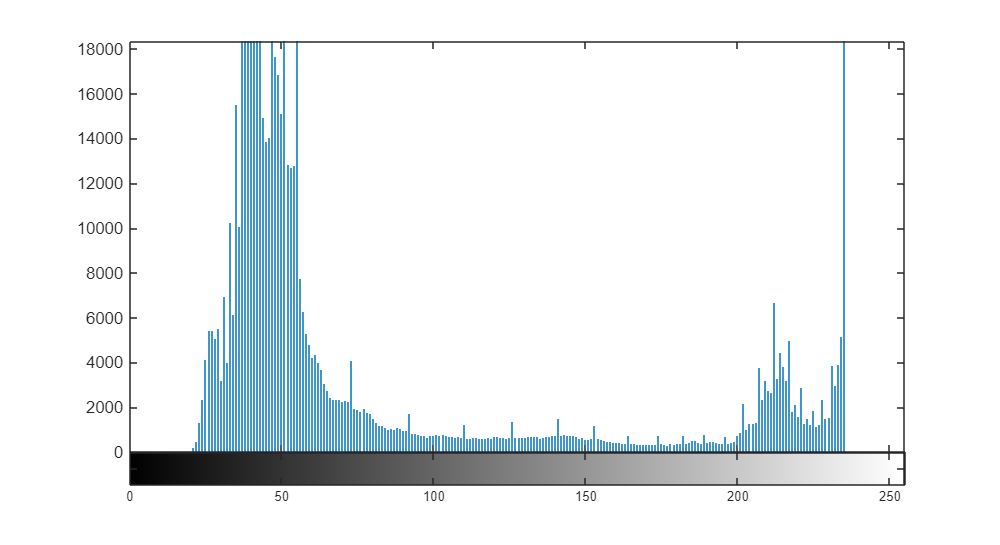

imhist(uint8(Ipp),256)

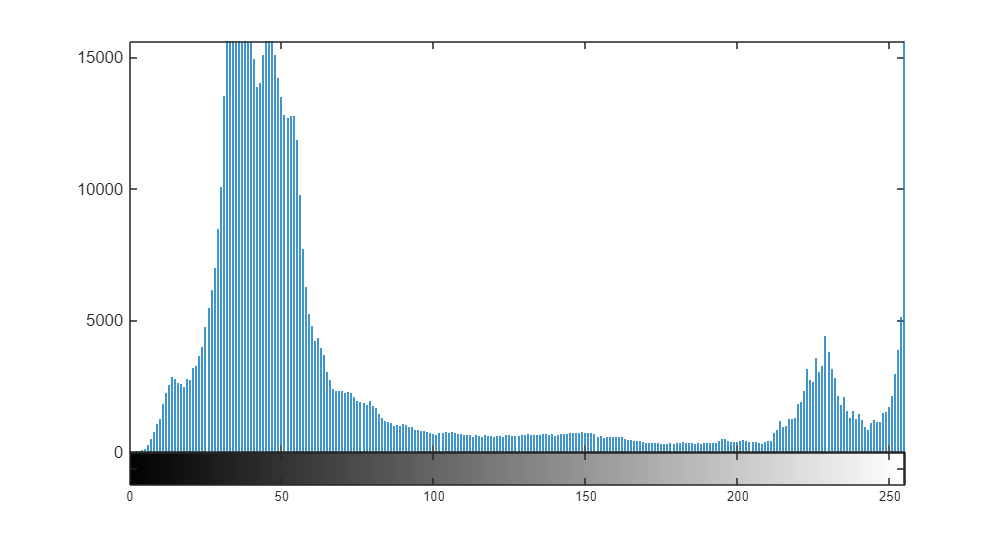

imhist(II,256)

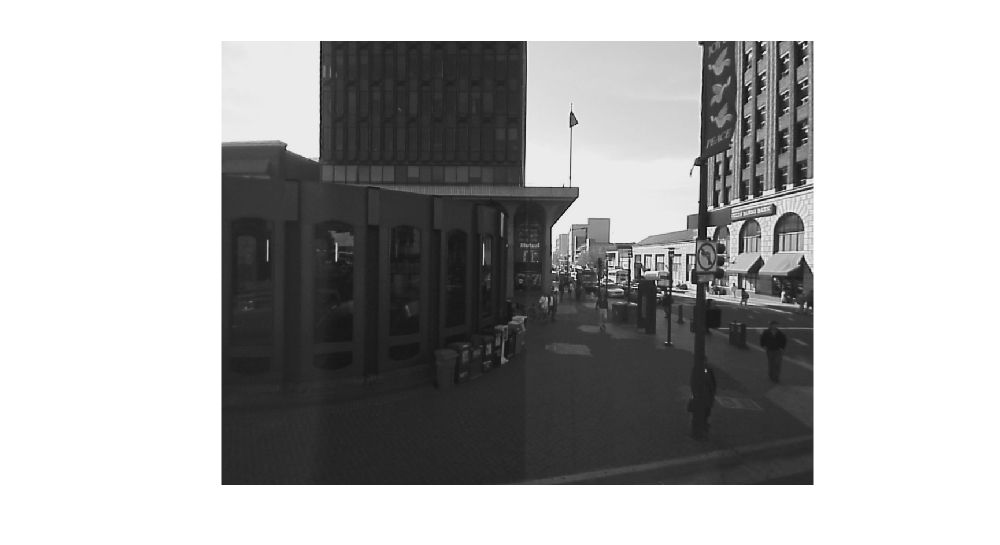

imshow(uint8(Ipp))

image sharpening

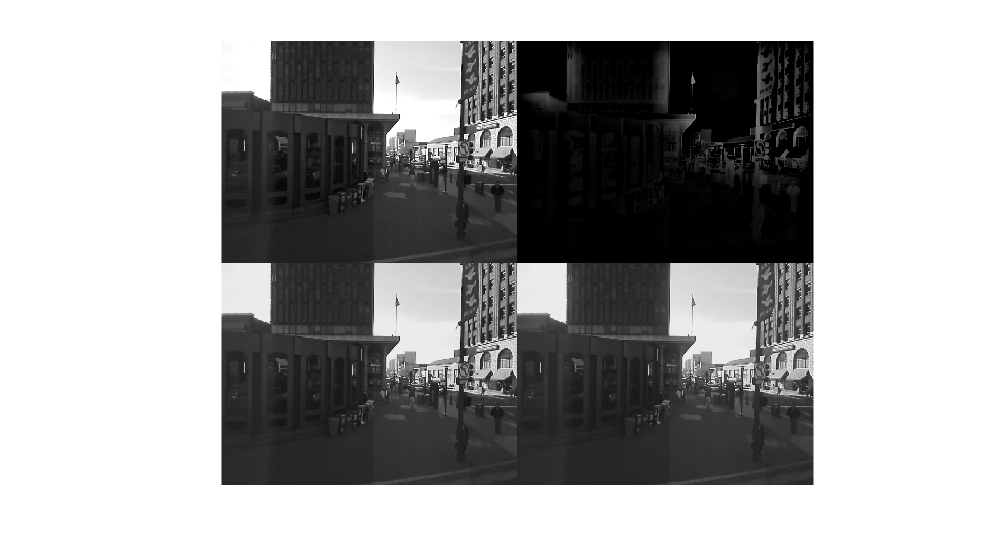

% Image sharpening using a high-pass filter created by subtracting a 
% low-pass Gaussian filter from an average filter.
% Set filter size
filter_size = 128;
% Define the standard deviation of the Gaussian filter
sigma = 0.125;
% Create the low-pass Gaussian filter
h = fspecial('gaussian', filter_size, sigma);
h_high = fspecial('average', filter_size) - h;
% Apply the low-pass filter to the image
high_pass_filtered_image = imfilter(uint8(Ipp),h_high);
Fpass = uint8(Ipp) + high_pass_filtered_image *0.2;
montage({II, high_pass_filtered_image , uint8(Ipp) , uint8(Fpass)})

finding sky

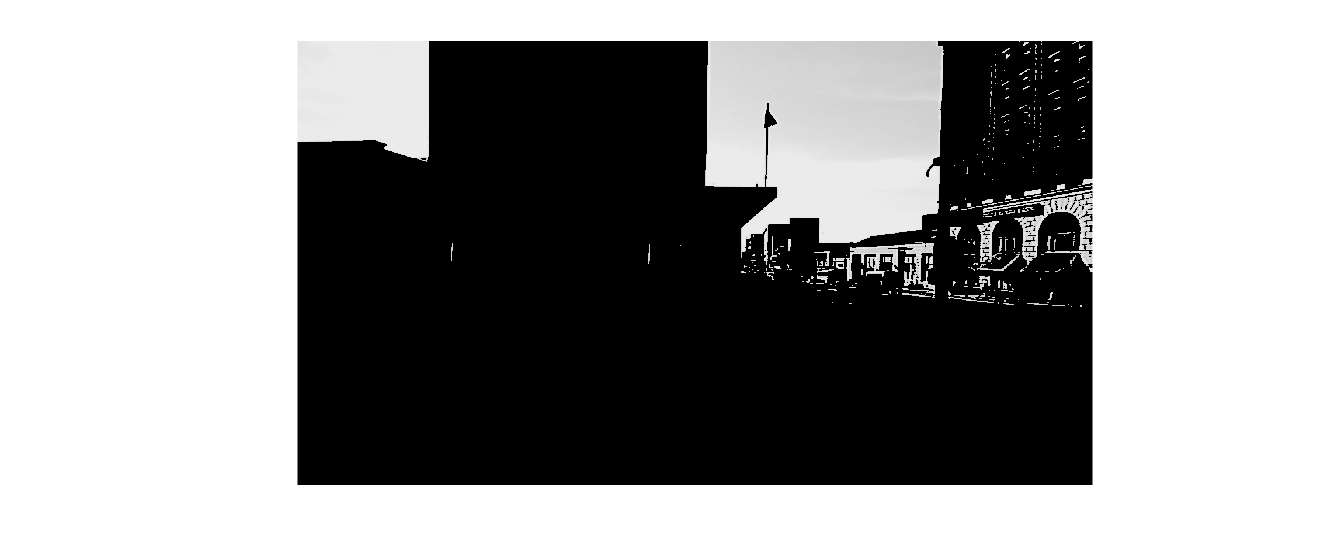

% Finding sky by thresholding pixel values and removing non-sky points 
% using morphological opening.
% Create a copy of the image
Ip = double(Fpass);
% Get the size of the image
[n , m] =size(Ip);
% Loop through each pixel in the image
for i=1:n
    for j=1:m
         % Set pixel value to 0 if it is less than 208
        if Ip(i,j)<196
            Ip(i,j)=0;
        end
    end
end
% Display the modified image
imshow(uint8(Ip))

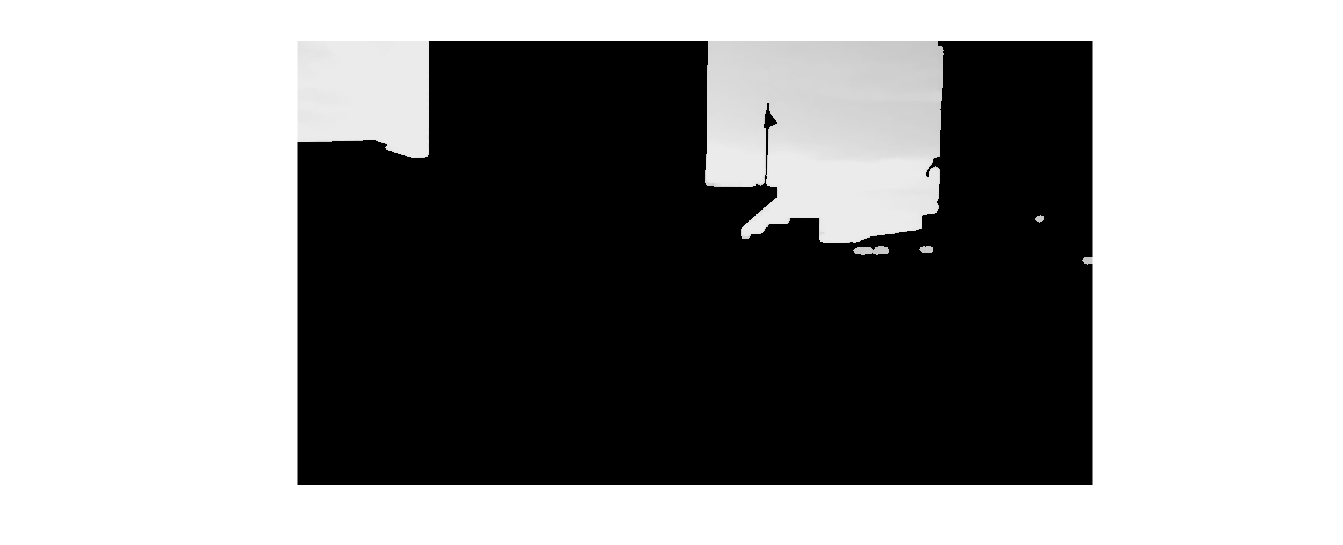

% Create a disk-shaped structuring element with radius
% 7 and 0 degrees of arc
se = strel('disk',5,0);
% Remove non-sky points from the image
Ipp = imopen(Ip,se);
Ipp = uint8(Ipp);
imshow(Ipp)

Remove the background from the original photo

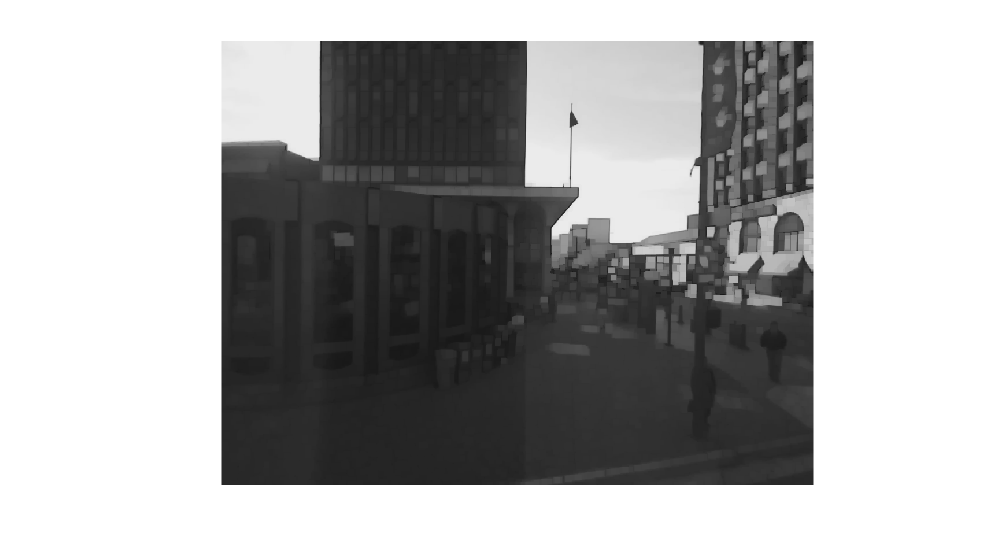

% Create a disk-shaped structuring element with radius
% 9 and 6 degrees of arc
se = strel('disk',5,6);
% Perform morphological opening on the original image 
% using the structuring element to approximate the background
background = imopen(Fpass,se);
% Display the background approximation image
imshow(background)

% Subtract a fraction of the background approximation image 
% from the original image and multiply by a factor to adjust contrast
I1 = 1.5*(Fpass - 0.4*background);
% Display the result of contrast adjustment
imshow(I1)

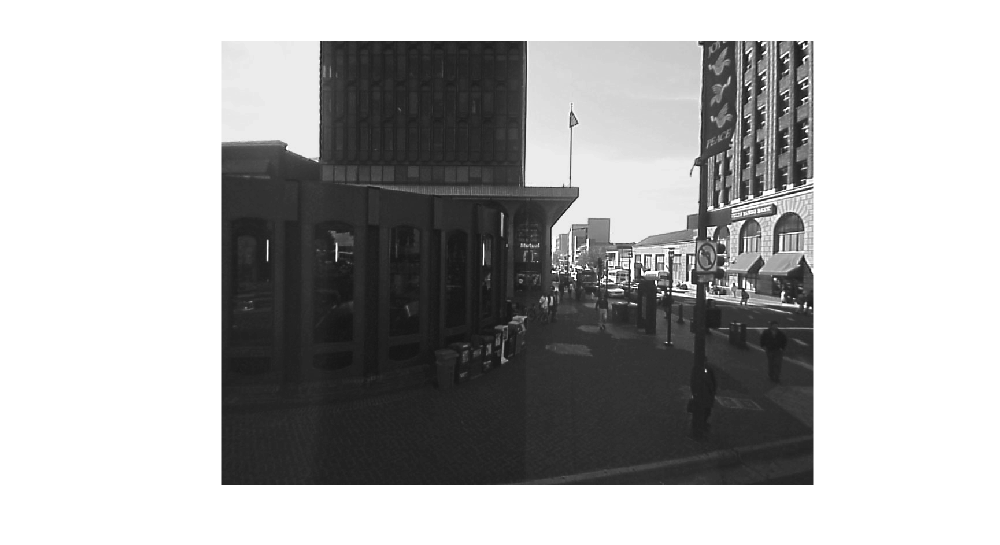

% add sky
I2 = I1 + 0.1*Ipp;
imshow(I2)

applying contrast correction filter

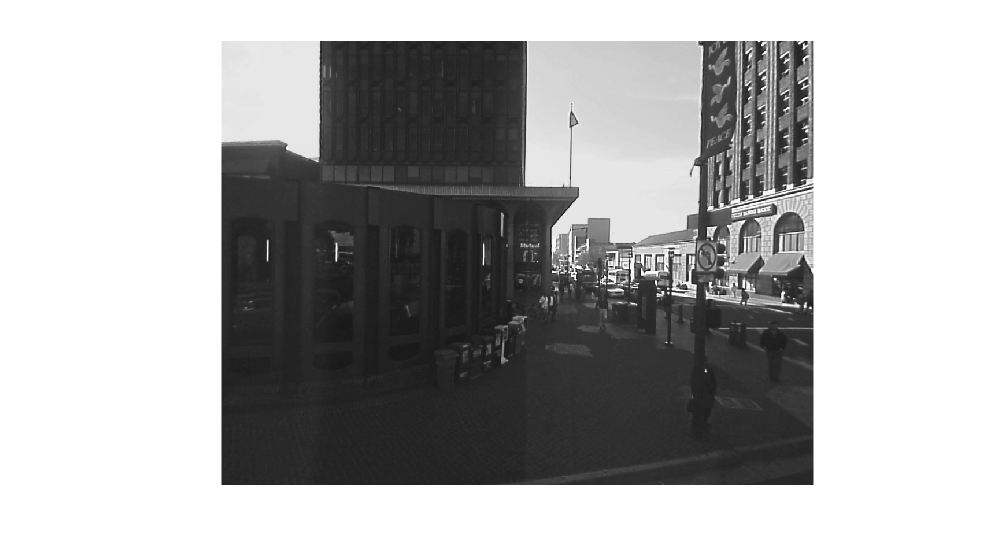

% Set parameters for local Laplacian filtering
sigma = 0.9;
alpha = 1.05;
beta  = 3; 
numLevels = 128;
% Perform local Laplacian filtering on the enhanced image using the 
% specified parameters and add a fraction of the result of morphological
% opening to enhance edges and details further
I3 = locallapfilt(I2, sigma, alpha, beta, 'NumIntensityLevels', numLevels);
imshow(I3)

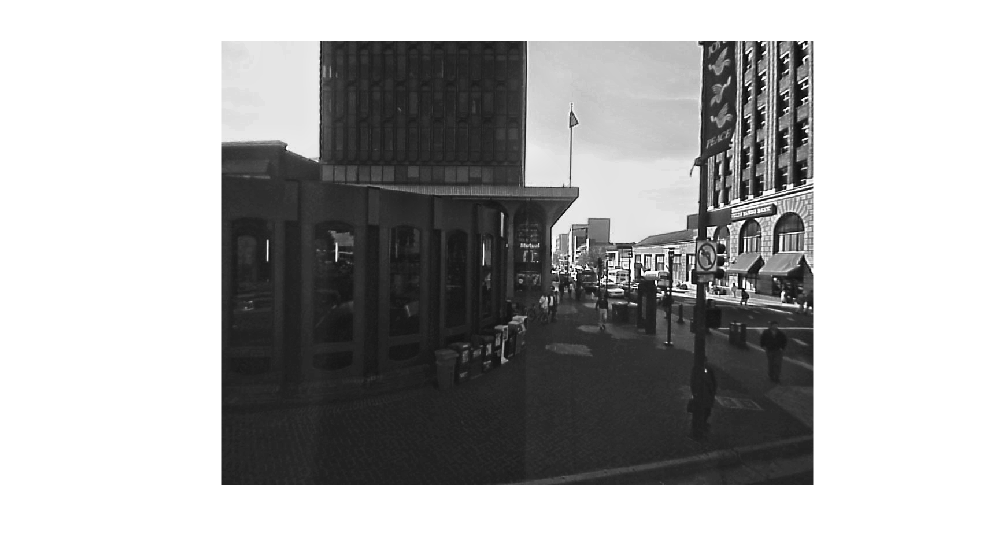

% Enhance contrast using adaptive histogram equalization with a custom clip limit
I4 = adapthisteq(I3,'NumTiles',[18 24],'ClipLimit', 0.003,'Distribution' ...
    ,'exponential','Alpha',0.35);
imshow(I4)

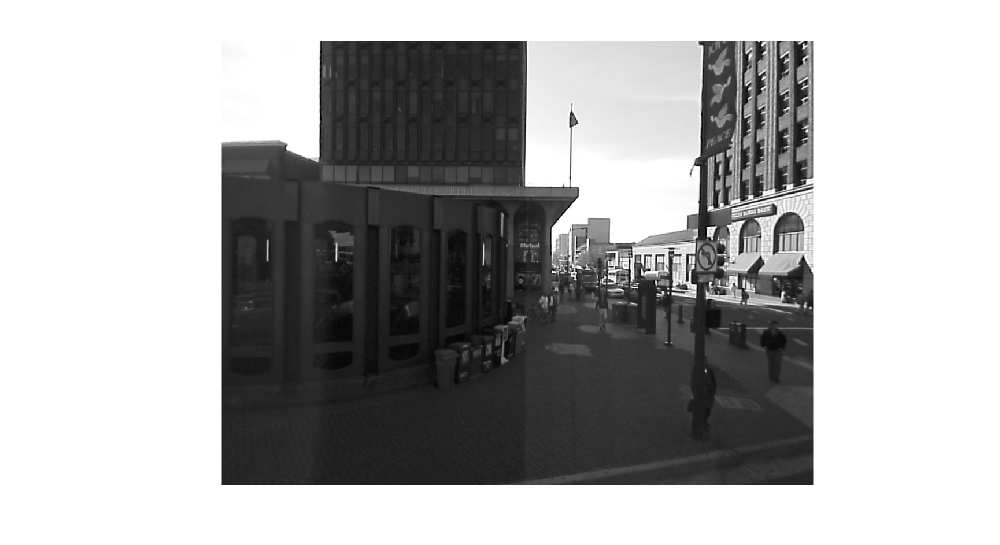

imshow(II)